# Exercise 2 bonus: Scale the input signal power.

This bonus exercise allows you to observe the effect of scaling the input signal power on the EVM.  

Using the slider below, scale the input waveform power.

## Scaling

p = addpath(genpath(pwd));

%%%%%%% Input Scaling %%%%%%%%%%%%
input_dBscale=1;
scaled_waveform=10^(input_dBscale/20)*Unimpaired_waveform;
%% Impairments%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Memoryless cubic nonlinearity
nonlin = comm.MemorylessNonlinearity(	'LinearGain', 		1, ...
    'IIP3', 					19, ...
    'AMPMConversion', 10);
scaled_waveform = nonlin(complex(scaled_waveform));

% IQ imbalance
scaled_waveform = iqimbal(scaled_waveform, 0.2, (180/pi)*0.5);

% Phase noise
phaseNoise = comm.PhaseNoise('FrequencyOffset', [10000 100000], ...
    'Level', 					[-95 -115], ...
    'SampleRate', 			Fs);
scaled_waveform = phaseNoise(scaled_waveform);

## Visualization

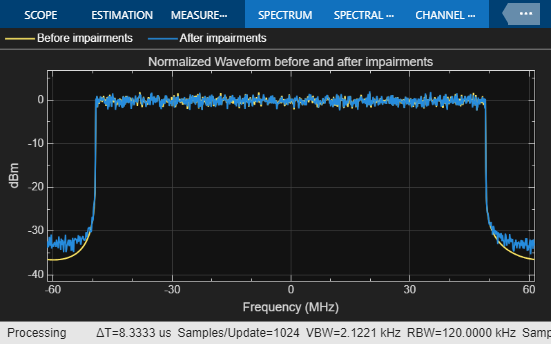


% %%%%%%%%%%%%%%%%%%%%%%%%%%%% Scope
sr = info.ResourceGrids.Info.SampleRate;
scope = spectrumAnalyzer('SampleRate',sr,...
    'ChannelNames',{'Before impairments','After impairments'},...
    'Title', 'Normalized Waveform before and after impairments');
s1=normalize(Unimpaired_waveform);
s2=normalize(scaled_waveform);
scope([s1,s2]);

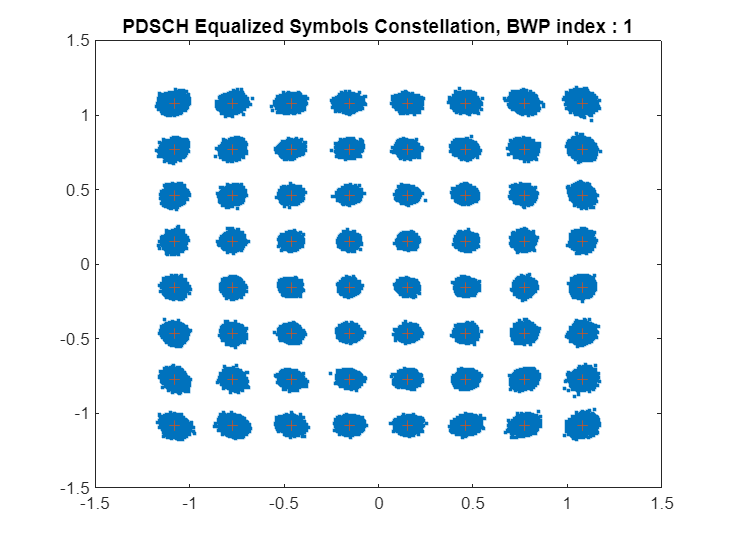


displayEVM=false;
plotEVM=false; 
IQImbalanceON=true;
cfg = struct();
cfg.Evm3GPP = evm3GPP;
cfg.TargetRNTIs = [];
cfg.PlotEVM = plotEVM;
cfg.DisplayEVM = displayEVM;
cfg.IQImbalance = IQImbalanceON;
%% EVM Calculation
[evmInfo,eqSym,refSym] = hNRDownlinkEVM(cfgDLTM,scaled_waveform,cfg);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Constellation diagram
figure
plot(cell2mat(eqSym),'.'); hold on
 plot(cell2mat(refSym),'+');
 title('PDSCH Equalized Symbols Constellation, BWP index : 1');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
disp([' Averaged overall PDSCH RMS EVM impaired: ' num2str(evmInfo.PDSCH.OverallEVM.RMS*100,'%.3f') ' %'])

 Averaged overall PDSCH RMS EVM impaired: 2.744 %


disp([' Averaged overall PDCCH RMS EVM impaired: ' num2str(evmInfo.PDCCH.OverallEVM.RMS*100,'%.3f') ' %'])

 Averaged overall PDCCH RMS EVM impaired: 2.900 %


path(p);